% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["ADC_pan_value", "ADC_tilt_value", "Button_value", "Encoder_tilt_value", "Encoder_pan_value", "Tilt_Velocity"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
joystick = readtable("/home/kasper/Documents/Civilingeniør_Robotteknologi/Semesterprojekt_4/CCS_workspace/Microcontroller_CCS/scripts/joystick.csv", opts);

% Clear temporary variables
clear opts

% Display results
joystick

joystick = 199×6 table
    ADC_pan_value    ADC_tilt_value    Button_value    Encoder_tilt_value    Encoder_pan_value    Tilt_Velocity
    _____________    ______________    ____________    __________________    _________________    _____________

        2048              2457              0                 285                   211                286     
        2048              2457              0                 290                   211                 52     
        2048              2457              0                 292                   211                 44     
        2048              2457              0                 299                   211                 97     
        2048              2457              0                 306                   211             

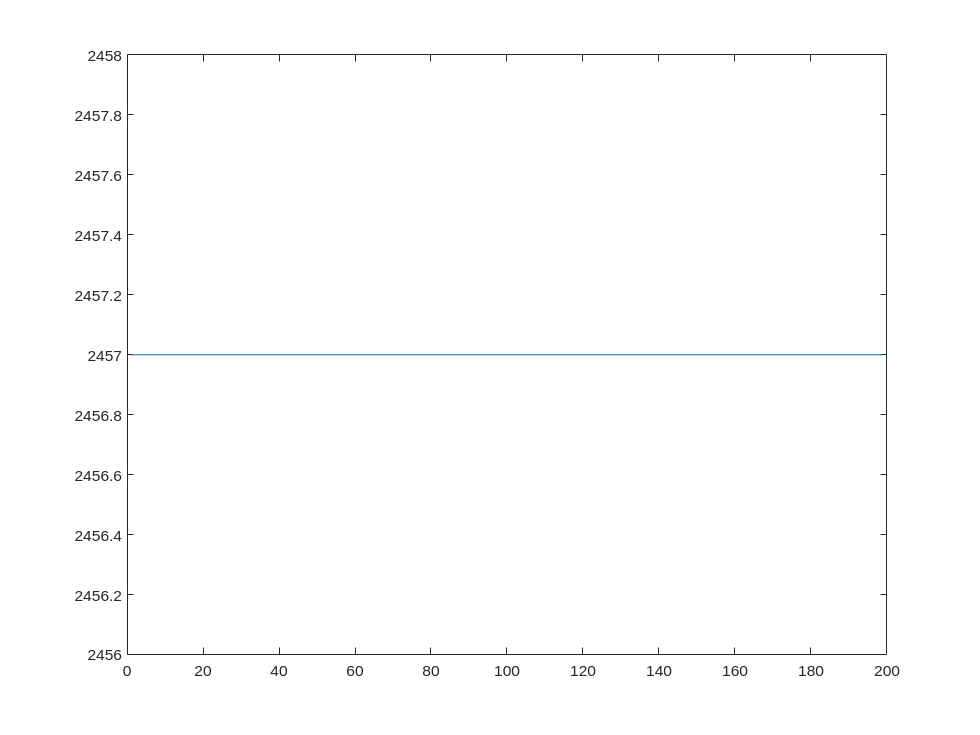

plot(joystick.ADC_tilt_value)

vel = plot(joystick.Encoder_tilt_value)

vel =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [285 290 292 299 306 318 326 330 330 331 332 333 342 346 2 27 61 103 135 140 130 109 92 93 109 136 157 164 159 149 145 146 158 167 183 194 197 197 196 196 197 202 208 217 228 239 244 246 246 247 249 256 265 270 280 287 289 291 … ]

  Show a

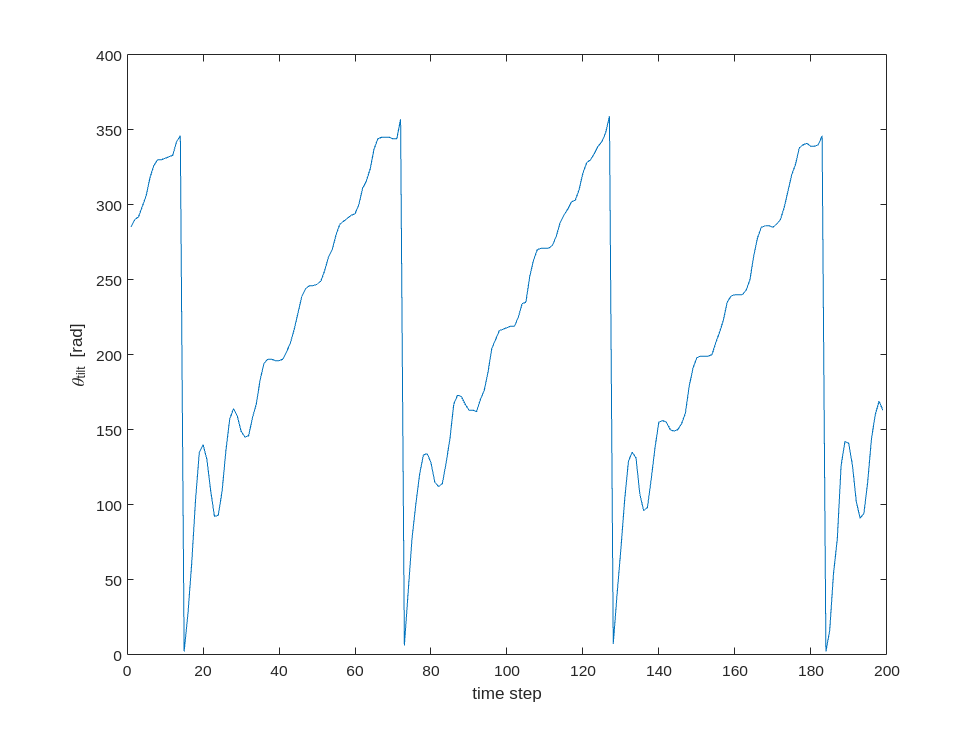

xlabel('time step')
ylabel('\theta_{tilt} [rad]')

exportgraphics(gcf, 'funny_plot.png')

Error using exportgraphics
The value of 'handle' is invalid. Specified handle is not valid for export.

%plot(joystick.Tilt_Velocity./100)